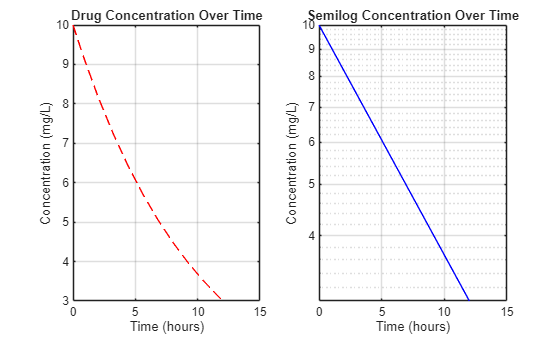

clear

% Define parameters
D = 100 ; % Dose
V = 10;  % Volume of distribution
CL = 5;  % Clearance rate
t = 0:0.1:12 ;   % Time variable


[t, C] = ode23(@wk3_class_101,[0 12],D/V);
% Plot
subplot(1,2,1),plot(t,C,'--r')
xlabel('Time (hours)');
ylabel('Concentration (mg/L)');
title('Drug Concentration Over Time');
grid on;
subplot(1,2,2), semilogy(t,C,'-b')
xlabel('Time (hours)');
ylabel('Concentration (mg/L)');
title('Semilog Concentration Over Time');
grid on;

clear

% Define parameters
D = 100 ; % Dose
V = 10;  % Volume of distribution
CL = 5;  % Clearance rate
t = [0:0.1:12] ;   % Time variable


sol = ode23(@wk3_class_101,[0 12],D/V);

% Solve the Concentration at the random time produced
C= deval(sol,t);

% Plot
figure()
subplot(1,2,1),plot(t,C,'--r')
xlabel('Time (hours)');
ylabel('Concentration (mg/L)');
title('Drug Concentration Over Time');
grid on;
subplot(1,2,2), semilogy(t,C,'*b')
xlabel('Time (hours)');
ylabel('Concentration (mg/L)');
title('Semilog Concentration Over Time');
grid on;
%To add other Variables to the functions other than t and C on the input
%in the function file, it need to be this way:

% Function of one compartment ODE
%function dCdt = wk3_class_101(t, C,CL, V)

% Define parameters
%V = 30;  % Volume of distribution
%CL = 3;  % Clearance rate
%k=CL/V;

% Calculate the rate of change of concentration
%dCdt = - CL/V * C;
%end




%Then on the script file, it need to be:

%% Define parameters
%D = 100 ; % Dose
%V = 10;  % Volume of distribution
%CL = 5;  % Clearance rate
%t = [0:0.1:12] ;   % Time variable

%options=odeset();    % Set Options for ODE

%sol = ode23(@wk3_class_101,[0 12],D/V, optionss,CL,V);

% Solve the Concentration at the random time produced
%C= deval(sol,t);







